# Average Precision (AP)

% Load data
load C:\Users\Andrea\Desktop\MAGISTRALE\Anno1-sem2\SearchEngines\HWS\seupd2021-goldr\RUN\RUN2020\RunAnalysis\runtotonlymap.mat

measure_ap = runtotonlymap(1:49,:);
measure_ap = table2array(measure_ap)

measure_ap =     0.6795    0.6795    0.6791    0.6826    0.6940
    0.3077    0.3077    0.3065    0.2759    0.3285
    0.3348    0.3348    0.3347    0.4506    0.4506
    0.3442    0.3288    0.3442    0.2586    0.2547
    0.2412    0.2452    0.2396    0.1159    0.1137
    0.3408    0.3354    0.3408    0.2038    0.1967
    0.2727    0.2774    0.2697    0.2075    0.2178
    0.1035    0.1035    0.1024    0.0233    0.0226
    0.2454    0.2487    0.2454    0.1703    0.1895
    0.2328    0.2286    0.2328    0.1725    0.1908




% remove the now useless ap matrix
clear runtotonlymap;

% the significance level
alpha = 0.05;

% the mean for each run across the topics
% Note that if the measure is AP (Average Precision), 
% this is exactly MAP (Mean Average Precision) for each run
m1 = mean(measure_ap);

% sort in descending order of mean score
[~, idx] = sort(m1, 'descend');

ogmyruns = "";
ogmyruns(1) = "run1";
ogmyruns(2) = "run2";
ogmyruns(3) = "run3";
ogmyruns(4) = "run4";
ogmyruns(5) = "run5";

% re-order runs by descending mean of the measure
measure_ap = measure_ap(:, idx);
myruns = ogmyruns;
myruns = myruns(:, idx);

## One way ANOVA

% perform the ANOVA
[~, tbl_ap, sts_ap] = anova1(measure_ap, myruns, 'off');

% display the ANOVA table
tbl_ap

tbl_ap = 4×6 cell array
    {'Source' }    {'SS'    }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Columns'}    {[0.1994]}    {[  4]}    {[  0.0499]}    {[  1.5630]}    {[  0.1849]}
    {'Error'  }    {[7.6556]}    {[240]}    {[  0.0319]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[7.8550]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double}


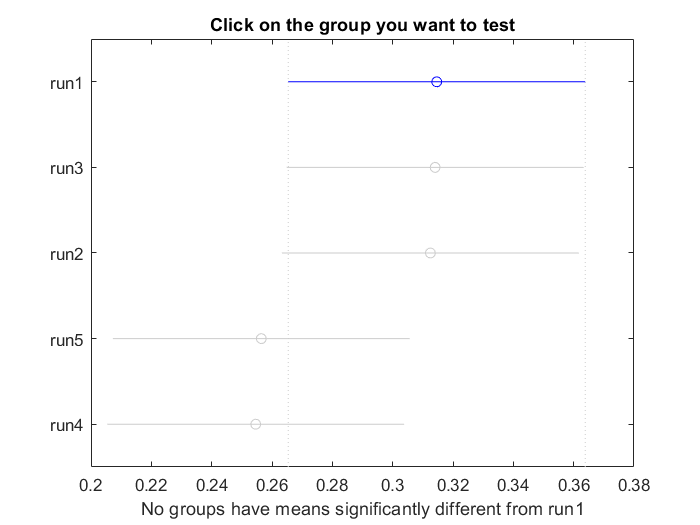


c = multcompare(sts_ap, 'Alpha', alpha, 'Ctype', 'hsd'); 


% display the multiple comparisons
c

c =     1.0000    2.0000   -0.0979    0.0005    0.0990    1.0000
    1.0000    3.0000   -0.0963    0.0021    0.1005    1.0000
    1.0000    4.0000   -0.0403    0.0582    0.1566    0.4896
    1.0000    5.0000   -0.0384    0.0600    0.1584    0.4569
    2.0000    3.0000   -0.0969    0.0016    0.1000    1.0000
    2.0000    4.0000   -0.0408    0.0576    0.1560    0.4993
    2.0000    5.0000   -0.0390    0.0595    0.1579    0.4664
    3.0000    4.0000   -0.0424    0.0561    0.1545    0.5274
    3.0000    5.0000   -0.0405    0.0579    0.1563    0.4942
    4.0000    5.0000   -0.0966    0.0019    0.1003    1.0000


## Two way ANOVA

% perform the ANOVA
[~, tbl2_ap, sts2_ap] = anova2(measure_ap, 1, 'off');

% display the ANOVA table
tbl2_ap

tbl2_ap = 5×6 cell array
    {'Source' }    {'SS'    }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'     }
    {'Columns'}    {[0.1994]}    {[  4]}    {[  0.0499]}    {[ 34.8793]}    {[ 7.0038e-22]}
    {'Rows'   }    {[7.3812]}    {[ 48]}    {[  0.1538]}    {[107.5816]}    {[1.6047e-115]}
    {'Error'  }    {[0.2744]}    {[192]}    {[  0.0014]}    {0×0 double}    {0×0 double   }
    {'Total'  }    {[7.8550]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double   }


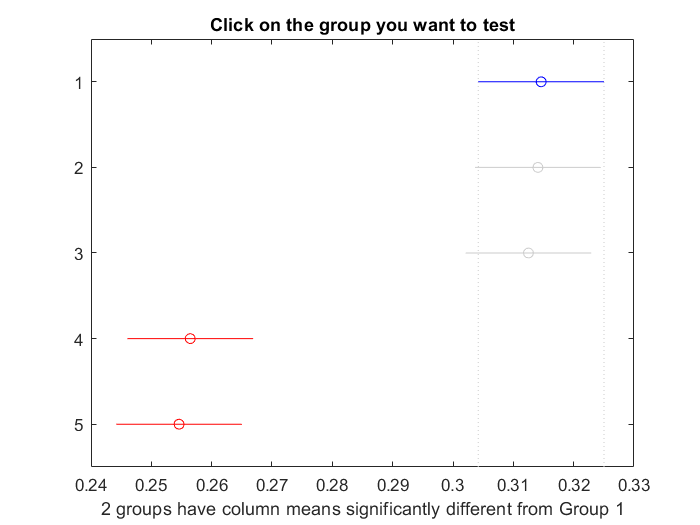

c2 =     1.0000    2.0000   -0.0203    0.0005    0.0214    1.0000
    1.0000    3.0000   -0.0187    0.0021    0.0229    0.9987
    1.0000    4.0000    0.0373    0.0582    0.0790    0.0000
    1.0000    5.0000    0.0392    0.0600    0.0809    0.0000
    2.0000    3.0000   -0.0193    0.0016    0.0224    0.9996
    2.0000    4.0000    0.0368    0.0576    0.0785    0.0000
    2.0000    5.0000    0.0386    0.0595    0.0803    0.0000
    3.0000    4.0000    0.0352    0.0561    0.0769    0.0000
    3.0000    5.0000    0.0371    0.0579    0.0787    0.0000
    4.0000    5.0000   -0.0190    0.0019    0.0227    0.9992


c2 = multcompare(sts2_ap, 'Alpha', alpha, 'Ctype', 'hsd', "Estimate","column")

 
c2

c2 =     1.0000    2.0000   -0.0203    0.0005    0.0214    1.0000
    1.0000    3.0000   -0.0187    0.0021    0.0229    0.9987
    1.0000    4.0000    0.0373    0.0582    0.0790    0.0000
    1.0000    5.0000    0.0392    0.0600    0.0809    0.0000
    2.0000    3.0000   -0.0193    0.0016    0.0224    0.9996
    2.0000    4.0000    0.0368    0.0576    0.0785    0.0000
    2.0000    5.0000    0.0386    0.0595    0.0803    0.0000
    3.0000    4.0000    0.0352    0.0561    0.0769    0.0000
    3.0000    5.0000    0.0371    0.0579    0.0787    0.0000
    4.0000    5.0000   -0.0190    0.0019    0.0227    0.9992


## BoxPlot

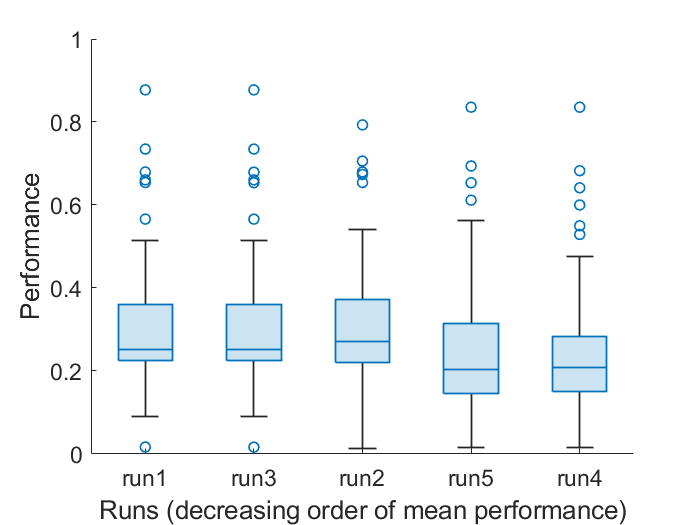

% Compute the mean performance of each run across topics
% This is the MAP for each run, if we loaded the AP data
m2 = mean(measure_ap);

% sort in descending order of mean score
[~, idx] = sort(m2, 'descend');

% re-order runs by descending mean of the measure
% needed to have a more nice looking box plot
measure_ap = measure_ap(:, idx);
myruns2 = myruns(:,idx);

figure

% show the box plot
boxchart(measure_ap)

%hold on

% plot the mean on top of the box plot
%plot (m, ':x', "MarkerSize", 10, "LineWidth", 2)

% adjust tick labels on x-axis, y-axis range, and font size
ax = gca;
ax.FontSize = 14;
ax.XTickLabel = myruns2;
xlabel("Runs (decreasing order of mean performance)")
ylabel("Performance")

TOTALComparisons = (length(myruns) * (length(myruns) - 1)) / 2

TOTALComparisons = 10

newmeasure = measure_ap(:, [1,3,2,5,4]);


Run run1 vs run2: p-value 0.506734

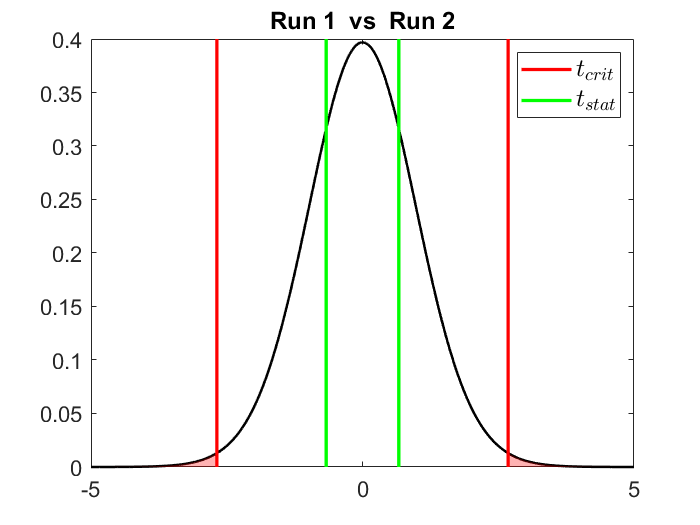

Run run1 vs run3: p-value 0.014658

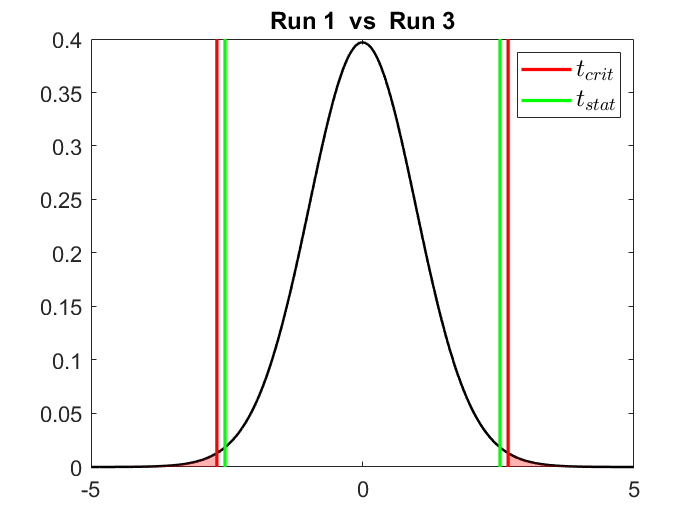

Run run1 vs run4: p-value 0.000000

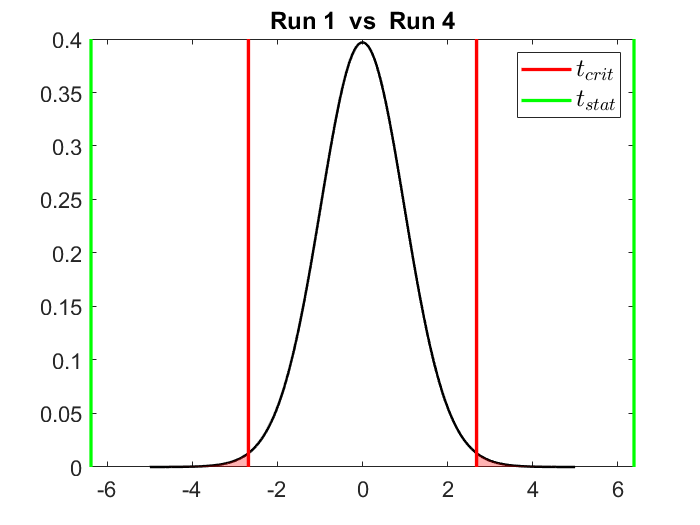

Run run1 vs run5: p-value 0.000000

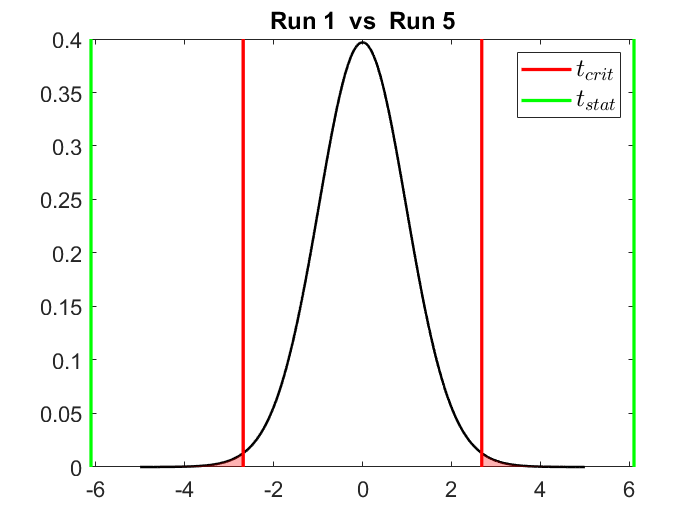

Run run2 vs run3: p-value 0.618248

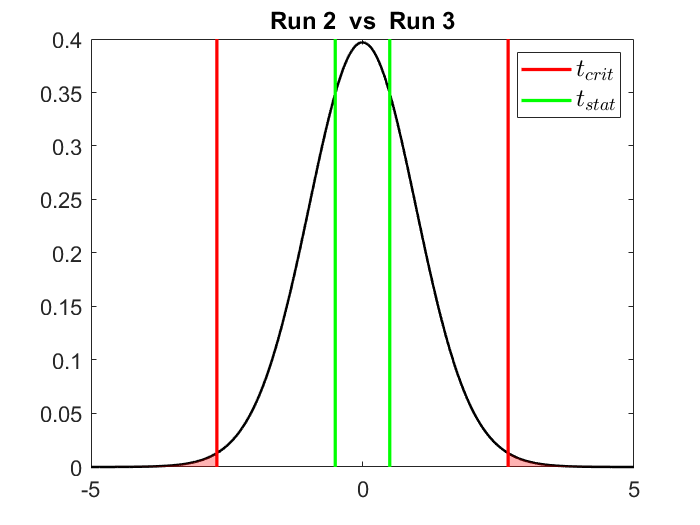

Run run2 vs run4: p-value 0.000001

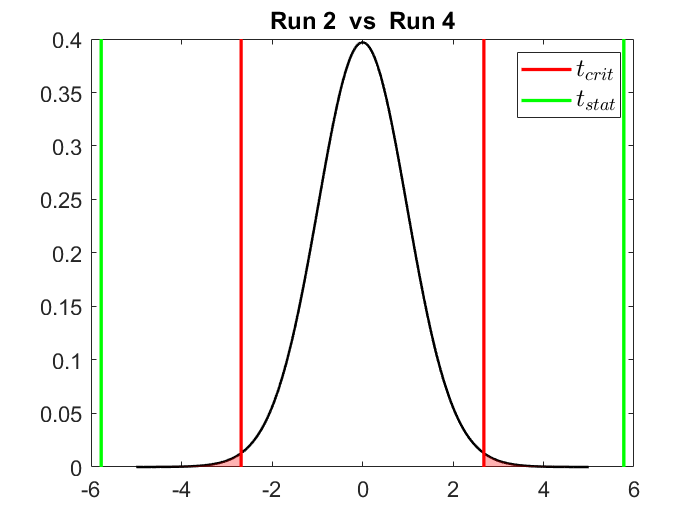

Run run2 vs run5: p-value 0.000001

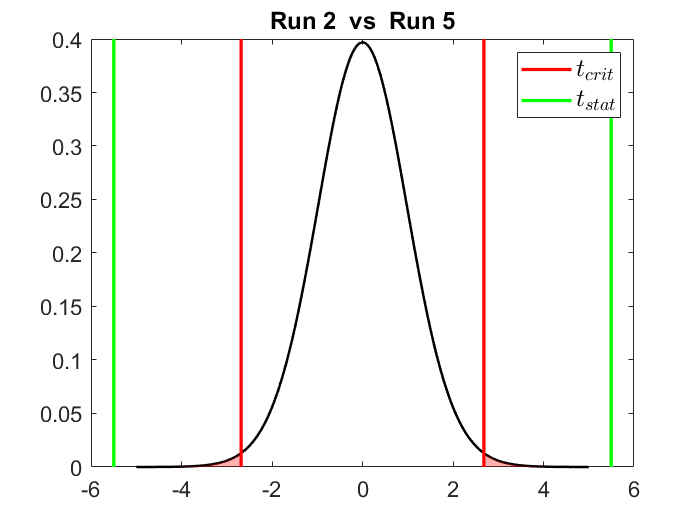

Run run3 vs run4: p-value 0.000000

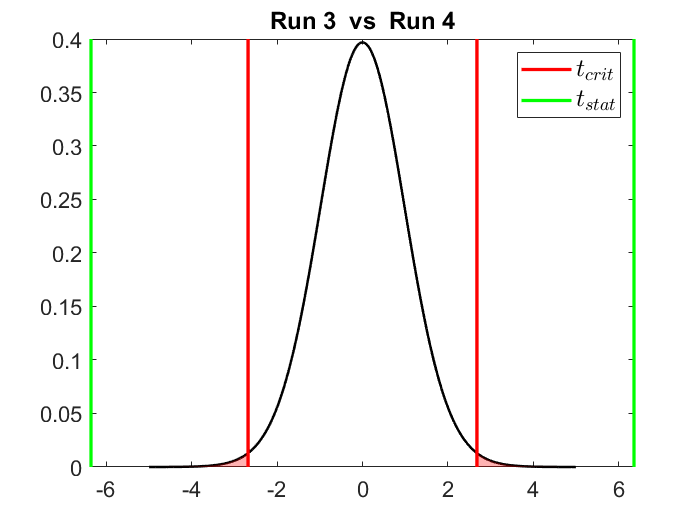

Run run3 vs run5: p-value 0.000000

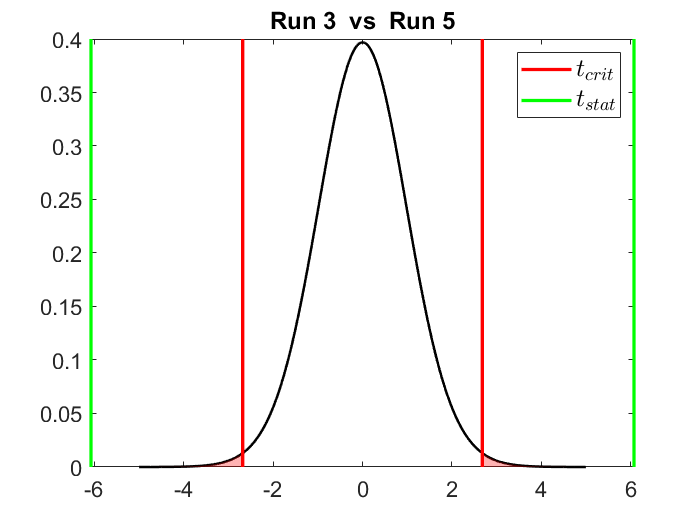

Run run4 vs run5: p-value 0.269019

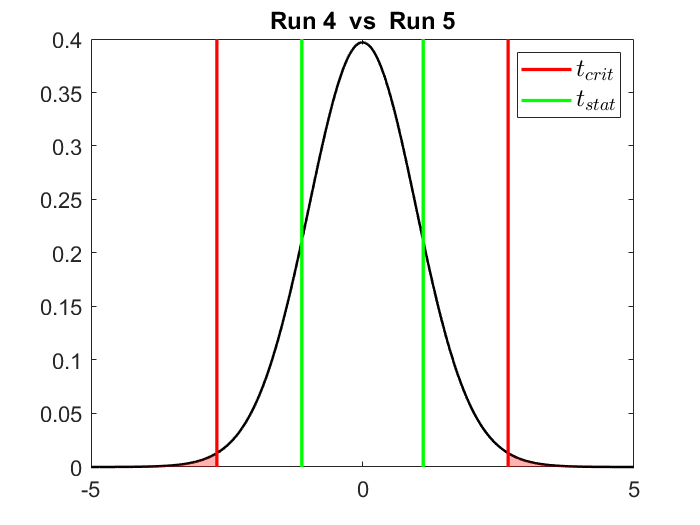

for r1 = 1:length(myruns)
    for r2 = 1:length(myruns)
        if r1 < r2
            %tstudnet comparisons
            %rna1 = myruns(r1);
            %rn1 = find(myruns==rna1);
            %rna2 = myruns(r2);
            %rn2 = find(myruns==rna2);
            
            [~, p] = ttest(newmeasure(:, r1), newmeasure(:, r2));
            fprintf("Run %s vs %s: p-value %f", ogmyruns(r1), ogmyruns(r2), p)
            df = length(newmeasure) - 1;
            tCrit = tinv(1 - 0.01/2, df);
            tRuns = tinv(1 - p/2, df);

            % t distribution 
            ar = -5:.01:5;
            ts = tpdf(ar, df);

            % find where we are above and below tCrit
            idx1 = ar >= tCrit;
            idx2 = ar <= -tCrit;
            
            figure

            plot(ar, ts, "LineWidth", 1.5, "Color", "k");
            
            hold on

            % plot two vertical lines corresponding to tCrit
            h(1) = plot([tCrit tCrit], get(gca, "ylim"), "Color", "r", "LineWidth", 2, "LineStyle", "-");
            plot([-tCrit -tCrit], get(gca, "ylim"), "Color", "r", "LineWidth", 2, "LineStyle", "-");

            % color the area under the t distribution above and below tCrit
            area(ar(idx1), ts(idx1) , "FaceColor", "r", "FaceAlpha", 0.3, "EdgeColor", "none");
            area(ar(idx2), ts(idx2), "FaceColor", "r", "FaceAlpha", 0.3, "EdgeColor", "none");
            
            h(2) = plot([tRuns tRuns], get(gca, "ylim"), "Color", "g", "LineWidth", 2, "LineStyle", "-");
            plot([-tRuns -tRuns], get(gca, "ylim"), "Color", "g", "LineWidth", 2, "LineStyle", "-");
            %xline(tRuns, "Color", "g", "LineWidth", 2);

            ax = gca;
            ax.FontSize = 13;
            %ax.YLim = [0 ax.YLim(2) + 0.05];
            %ax.XLim = [-5, 5];
            title(['Run ',num2str(r1),'  vs  Run ',num2str(r2)])
            
            lgnd = legend([h(1), h(2)], ["$t_{crit}$", "$t_{stat}$"], "Interpreter", "Latex");
            lgnd.FontSize = 15;
            
            %fprintf("%d - %d \n", r1, r2)
            if r2 == 5
                break
            end
        end
    end
end